% Leave-one-patient-out cross-validation linear discriminant analysis classifier with LASSO-based feature selection

%  MATLAB version: MATLAB R2025a
% Required toolboxes:
% - Statistics and Machine Learning Toolbox

% DESCRIPTION:
% This script performs leave-one-patient-out cross-validation 
% using a linear discriminant analysis classifier.
%
% Feature selection is performed independently within each training fold
% using LASSO logistic regression followed by Pearson correlation filtering.
%
% The workflow is designed to prevent information leakage by restricting
% all feature selection steps to the training partition.
%
% INPUT:
% An Excel (.xlsx) feature table containing:
%   Column 1: ID (participant identifier)
%   Column 2: Truth (binary outcome: 0/1)
%   Remaining columns: quantitative radiomic features
%
% OUTPUT:
%   - ROC curve
%   - Area under the ROC curve (AUC)
%   - Classification scores
%   - Confusion matrix
%   - Overall classification accuracy
%   - Feature selection frequency
%   - Optional Pearson correlation heatmap
%   - Results saved as LOPO_LDA_results.mat

clear
clc

% Initialize variables

% Read feature file: ID (first column) Truth (second column) Features,
% rows=participants in study
featureFile = 'input file path here';
mrf = readtable(featureFile);

f1 = 18×95 table
       ID       Truth    original_firstorder_10Percentile    original_firstorder_90Percentile    original_firstorder_Energy    original_firstorder_Entropy    original_firstorder_InterquartileRange    original_firstorder_Kurtosis    original_firstorder_Maximum    original_firstorder_MeanAbsoluteDeviation    original_firstorder_Mean    original_firstorder_Median    original_firstorder_Minimum    original_firstorder_Range    original_firstorder_RobustMeanAbsoluteDeviation    original_firstorder_RootMeanSquared    original_firstorder_Skewness    original_firstorder_TotalEnergy    original_firstorder_Uniformity    original_firstorder_Variance

f2 = 11×95 table
        ID        Truth    original_firstorder_10Percentile    original_firstorder_90Percentile    original_firstorder_Energy    original_firstorder_Entropy    original_firstorder_InterquartileRange    original_firstorder_Kurtosis    original_firstorder_Maximum    original_firstorder_MeanAbsoluteDeviation    original_firstorder_Mean    original_firstorder_Median    original_firstorder_Minimum    original_firstorder_Range    original_firstorder_RobustMeanAbsoluteDeviation    original_firstorder_RootMeanSquared    original_firstorder_Skewness    original_firstorder_TotalEnergy    original_firstorder_Uniformity    original_firstorder_Variance

mrf = 29×95 table
       ID       Truth    original_firstorder_10Percentile    original_firstorder_90Percentile    original_firstorder_Energy    original_firstorder_Entropy    original_firstorder_InterquartileRange    original_firstorder_Kurtosis    original_firstorder_Maximum    original_firstorder_MeanAbsoluteDeviation    original_firstorder_Mean    original_firstorder_Median    original_firstorder_Minimum    original_firstorder_Range    original_firstorder_RobustMeanAbsoluteDeviation    original_firstorder_RootMeanSquared    original_firstorder_Skewness    original_firstorder_TotalEnergy    original_firstorder_Uniformity    original_firstorder_Variance


requiredColumns = {'ID','Truth'};

assert(all(ismember(requiredColumns,mrf.Properties.VariableNames)),...
    'Input file must contain ID and Truth columns');

assert(all(ismember(unique(mrf.Truth),[0 1])),...
    'Truth variable must be binary (0/1)');

% Pearson correlation threshold used to remove redundant features.
% Features with |r| > 0.70 were considered highly correlated.
correlationValue = 0.7; 

generateCorrelationHeatmap = true;

% Final uncorrelated features used for classification in training partition
featsKept= [];

% Organized LDA scores
classificationScores= [];

% Organized LDA truth
classificationTruth= [];

% Tracking performance for given subject
id_order= [];


% IMPORTANT:
% Feature selection, correlation filtering, and model fitting are performed
% independently within each training fold of leave-one-patient-out
% cross-validation to prevent test-set information leakage.

cv = cvpartition(height(mrf),'LeaveOut');
for i=1:cv.NumTestSets
    tr=cv.training(i);
    te=cv.test(i);
    
    id_order=[id_order;mrf.ID(te)];
    
    % This assumes features start after Truth column
    fidx = find(string(mrf.Properties.VariableNames) == "Truth")+1;
    midx = width(mrf);

    train_set=mrf(tr,fidx:midx);
    test_set=mrf(te,fidx:midx);

    train_class=mrf.Truth(tr);
    test_class=mrf.Truth(te);
    
   % Perform LASSO logistic regression feature selection only within
   % the training partition to prevent information leakage into the test set.
   % The lambda minimizing cross-validated deviance is selected.
    
    features = transpose(train_set.Properties.VariableNames);
    [B,FitInfo] = lassoglm(table2array(train_set), train_class,"binomial", 'CV', 5,'Alpha', 1,'PredictorNames',features,'Standardize',true);
    idxLambdaMin = FitInfo.IndexMinDeviance;
    selectedFeatures = FitInfo.PredictorNames(B(:, idxLambdaMin) ~= 0);

    LASSOfeatures = transpose(selectedFeatures); % Organizing features selected from LASSO
    
    % Removes features from train_set and test_set not selected by
    % LASSO
    for d = 1:height(features)
        feat = features{d,1};
        fidx = find(string(LASSOfeatures) == string(feat));
        if isempty(fidx)
            tidx = find(string(train_set.Properties.VariableNames) == string(feat));
            train_set(:,tidx) = [];
            test_set(:,tidx) = [];
        end
    end
   
    % Calculating correlation coefficients
    x = corrcoef(table2array(train_set));
    rhoFeats = transpose(train_set.Properties.VariableNames);
    for v = 1:width(x)
        for y = 1:height(x)
            if (v==y)==0 % Not looking at same feature
                if abs(x(y,v)) > correlationValue % Choosing a correlation cutoff point
                    x(y,v) = NaN; % Flagging as highly correlated
                end
            end
        end
    end
    uncorrRhoFeats = rhoFeats; % Making duplicated table to keep track of feats uncorrelated/not deleted yet
    for n = 1:height(rhoFeats)
        feat = rhoFeats{n,1};
        if isempty(find(string(uncorrRhoFeats) == string(feat)))
            continue
        else
            tidx = find(isnan(x(n,:))); % Find flagged (highly correlated) features
            for o = 1:width(tidx)
                deleteFeat = rhoFeats{tidx(1,o),:};
                fidx = find(string(uncorrRhoFeats) == string(deleteFeat));
                uncorrRhoFeats(fidx,:) = [];
            end
        end
    end

    % The final list of uncorrelated features
    total = uncorrRhoFeats;
    
    % Keeping track of uncorrelated features selected in each training iteration
    featsKept = [featsKept; uncorrRhoFeats];
    
    % Keeping the uncorrelated features in the testing and training set
    newTrain=[];
    newTest=[];
    for j=1:height(total)
        feat=total{j,1};
        tidx = find(string(train_set.Properties.VariableNames) == string(feat));
        newTrain=[newTrain train_set{:,tidx}];
        newTest=[newTest test_set{:,tidx}];
    end
    
    % The final training and testing for building model and prediction
    train_set=newTrain;
    test_set=newTest;
    
    % Train linear discriminant analysis classifier
    pkdMdl = fitcdiscr(train_set,train_class); 

    % Predict posterior probability for held-out participant
    [label,score] = predict(pkdMdl,test_set);
    
    % LDA scores
    % Store posterior probability of positive class (Truth=1)
    classificationScores=[classificationScores;score(:,2)];
    classificationTruth=[classificationTruth;test_class];
    
end

% Final performance across all subjects of the leave-one-out LDA

[X,Y,T,AUC_lda] = perfcurve(classificationTruth,classificationScores,1,'NBoot',1000); 

% Scores of each subject
classification_scores=[string(id_order) classificationScores classificationTruth];

% Organized classification output 
rockit=[classificationScores classificationTruth];
rockit=sortrows(rockit, 2, 'ascend');

% Confusion matrix using a posterior probability threshold of 0.5
predictedClass = classificationScores >= 0.5;
trueClass = classificationTruth == 1;

TP = sum(predictedClass & trueClass);
FP = sum(predictedClass & ~trueClass);
FN = sum(~predictedClass & trueClass);
TN = sum(~predictedClass & ~trueClass);

accuracy = (TP + TN) / numel(trueClass);

confusionMatrix = [TP FN;
                   FP TN];

% The proportion that each feature was selected across the leave-one-out
% model
g=table;
f=unique(featsKept);

for i=1:height(f)
    f1=f(i,1);
    index=contains(featsKept(:,1),f1);
    row=find(index==1);
    g(i,1)=f1;
    g{i,2}=height(row);
end


g=sortrows(g,2,'descend');

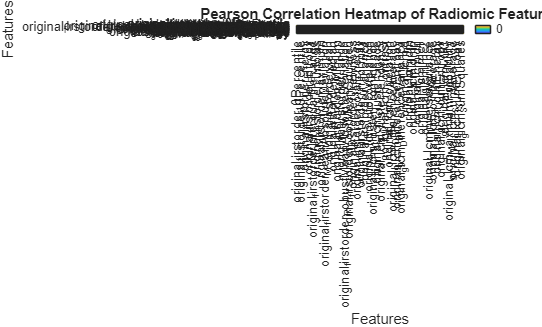

% Compute Pearson correlation matrix of radiomic features
if generateCorrelationHeatmap
    fidx = find(string(mrf.Properties.VariableNames) == "Truth")+1;
    midx = width(mrf);
    
    featureNames = mrf.Properties.VariableNames(fidx:midx);
    featureData = table2array(mrf(:,fidx:midx));
    
    [corrMatrix, ~] = corr(featureData, 'Type', 'Pearson', 'Rows', 'pairwise');
    
    % Create a heatmap from the correlation matrix
    figure;
    h = heatmap(featureNames, featureNames, corrMatrix, ...
        'Colormap', parula, 'ColorLimits', [-1 1]);
    
    % Add labels and title
    h.Title = 'Pearson Correlation Heatmap of Radiomic Features';
    h.XLabel = 'Features';
    h.YLabel = 'Features';

end

% Save classification results and feature selection summary
save('LOPO_LDA_results.mat',...
    'classification_scores',...
    'AUC_lda',...
    'X',...
    'Y',...
    'T',...
    'accuracy',...
    'confusionMatrix',...
    'g')